Newton-Raphson


syms x
f=exp(-x)-x;
fx(1)=1;
tol=0.5;
d=diff(f);
d=inline(d);
f=inline(f);
ea(1)=100;
iter(1) = 1;
i=1;
while abs(ea(i))>=tol
xi(i+1)=fx(i)-(f(fx(i))/d(fx(i)));
ea(i+1)=abs(((xi(i)-fx(i))/xi(i))*100);
fx(i+1)=xi(i);
iter(i+1) = i;
i=i+1;
end
 table(iter',xi',ea','VariableNames',{'I','Xr','Ea'})

ans = 6×3 table
    I      Xr         Ea   
    _    _______    _______

    1          0        100
    1    0.53788        Inf
    2        0.5        100
    3    0.56699     7.5766
    4    0.56631     11.815
    5    0.56714    0.11937


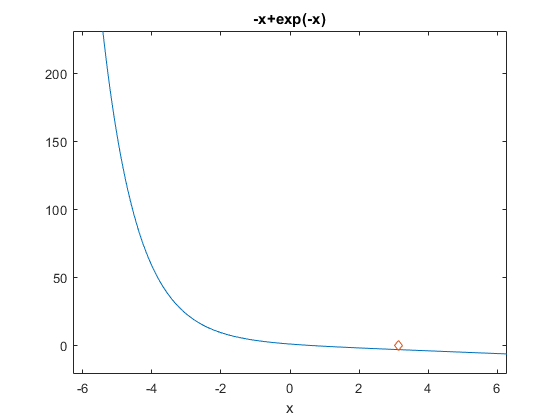


ezplot(f)
hold on
plot(pi,0,'d')
hold off

clear all
clc
syms x
f=cos(x)-(x*exp(x));
fx(1)=2;
tol=10;
d=diff(f);
d=inline(d);
f=inline(f);
ea(1)=100;
iter(1) = 1;
i=1;
while abs(ea(i))>=tol
xi(i+1)=fx(i)-(f(fx(i))/d(fx(i)));
ea(i+1)=abs(((xi(i)-fx(i))/xi(i))*100);
fx(i+1)=xi(i);
iter(i+1) = i;
i=i+1;
end
 table(iter',xi',ea','VariableNames',{'I','Xr','Ea'})

ans = 9×3 table
    I      Xr         Ea  
    _    _______    ______

    1          0       100
    1     1.3416       Inf
    2          1       100
    3     0.8477    34.157
    4    0.65308    17.966
    5    0.58756    29.801
    6    0.53134    11.152
    7    0.52158    10.579
    8    0.51791    1.8717


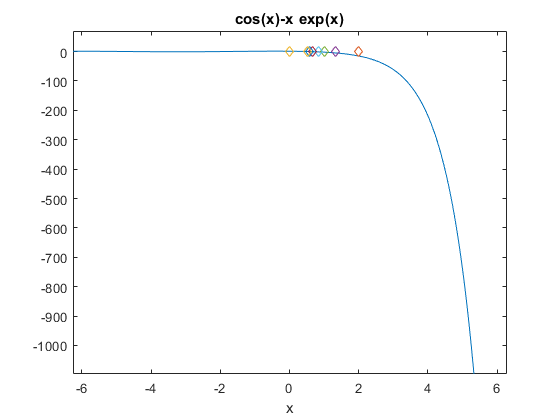


ezplot(f)
hold on
plot(fx,0,'d')
hold off


clc
syms x
f=x^4-x-10;
fx(1)=2;
tol=10;
d=diff(f);
d=inline(d);
f=inline(f);
ea(1)=2;
iter(1) = 1;
i=1;
xi(1)=f;

The following error occurred converting from inline to double:
Conversion to double from inline is not possible.

while abs(ea(i))>=tol
xi(i+1)=fx(i)-(f(fx(i))/d(fx(i)));
ea(i+1)=abs(((xi(i)-fx(i))/xi(i))*100);
fx(i+1)=xi(i);
iter(i+1) = i;
i=i+1;
end

 table(iter',xi',ea','VariableNames',{'I','Xr','Ea'})

 

%Graficamos la función
ezplot(f)

Undefined function or variable 'f'.

hold on
plot(pi,0,'d')
hold off